# Forward Kinematics

## Modeling and Control of Robotic Manipulators

## Denavit-Hartenberg Parameters UR10

#### 1. DH parameters

Figure 4 illustrates the coordinate frames associated with the UR10 robot arm. Table 1 reports the DH parameter $$a_i, d_i$$. Complete the table by adding the parameters $$\alpha_i$$ according to the figure 4.

alpha = [pi/2 0  0 pi/2 -pi/2 0]

alpha =     1.5708         0         0    1.5708   -1.5708         0


#### 2. Homogeneous transormation

Define the homogeneous transform  *shoulderlink* that corresponds to the DH-parameters $$a_1,\alpha_1,d_1,\theta_1$$  for $$\theta_1=\pi/4$
$ (see lab on spatial transformations).

a=0;
alpha=pi/2;
d=0.1273;
theta=pi/4;

trvecx=[a 0 0];
trvecz=[0 0 d];
rotmx = [1 0 0; 0 cos(alpha) -sin(alpha); 0 sin(alpha) cos(alpha)];
rotmz = [cos(theta) -sin(theta) 0; sin(theta) cos(theta) 0; 0 0 1]; 

tformtx=trvec2tform(trvecx);
tformtz=trvec2tform(trvecz);
tformrotx=rotm2tform(rotmx);
tformrotz=rotm2tform(rotmz);

shoulderlink=tformtz*tformrotz*tformtx*tformrotx

shoulderlink =     0.7071   -0.0000    0.7071         0
    0.7071    0.0000   -0.7071         0
         0    1.0000    0.0000    0.1273
         0         0         0    1.0000


## Joint Configuration and Transforms

#### 3. Rigid Body Tree

Define a *RigidBodyTree* object *robot*.  Define a *RigidBody* *baselink* with fixed joint *worldjoint* to define a fixed transformation from the world coordinate frame to the base frame. The fixed transform is a displacement $$d=1$$ along the z-axis plus a rotation around the z-axis by $$\pi$$.  That reflects the distance of $$1m$$ the robot base is mounted above the ground plane and complies with the ROS URDF-description of the UR10 robot. It could be later modified to relocate the robot base w.r.t. a world frame. Add the body *baselink* to your *robot*.

robot = robotics.RigidBodyTree;
robot.BaseName='world';
baselink = robotics.RigidBody('baselink');
jnt0 = robotics.Joint('worldjoint','fixed');
jnt0.setFixedTransform([0 0 1 pi],'dh');
baselink.Joint = jnt0;
robot.addBody(baselink,'world');

#### 4. Define shoulderlink

Define a *RigidBody shoulderlink* with a revolute joint *shoulderpanjoint*. Specify the DH parameters of the first revolute joint according to table 1. Add the body *shoulderlink* to your robot such that it becomes child of the parent *baselink*. 

shoulderlink = robotics.RigidBody('shoulderlink');
jnt1 = robotics.Joint('shoulderpanjoint','revolute');
jnt1.setFixedTransform([0 pi/2 0.1273 0],'dh');
shoulderlink.Joint = jnt1;
robot.addBody(shoulderlink,'baselink');

#### 5. Verify the structure

Verify the rigid body tree structure with *showdetails* which output should look like in the pdf.

robot.showdetails

--------------------
Robot: (2 bodies)

 Idx           Body Name              Joint Name              Joint Type           Parent Name(Idx)   Children Name(s)
 ---           ---------              ----------              ----------           ----------------   ----------------
   1            baselink              worldjoint                   fixed                   world(0)   shoulderlink(2)  
   2        shoulderlink        shoulderpanjoint                revolute                baselink(1)   
--------------------


#### 6. Add bodies and joints

Proceed in the same manner and consecutively add bodies and joints for *upperarmlink, shoulderliftjoint, forearmlink, elbowjoint, wrist1link, wrist1joint,  wrist2link, wrist2joint, wrist3link, wrist3joint*. All of the joints are revolute, and the DH parameters are listed in table 1.

upperarmlink = robotics.RigidBody('upperarmlink');
jnt2 = robotics.Joint('shoulderliftjoint','revolute');
jnt2.setFixedTransform([-0.612 0 0 0],'dh');
upperarmlink.Joint = jnt2;
robot.addBody(upperarmlink,'shoulderlink');

forearmlink = robotics.RigidBody('forearmlink');
jnt3 = robotics.Joint('elbowjoint','revolute');
jnt3.setFixedTransform([-0.5723 0 0 0],'dh');
forearmlink.Joint = jnt3;
robot.addBody(forearmlink,'upperarmlink');

wrist1link = robotics.RigidBody('wrist1link');
jnt4 = robotics.Joint('wrist1joint','revolute');
jnt4.setFixedTransform([0 pi/2 0.163941 0],'dh');
wrist1link.Joint = jnt4;
robot.addBody(wrist1link,'forearmlink');

wrist2link = robotics.RigidBody('wrist2link');
jnt5 = robotics.Joint('wrist2joint','revolute');
jnt5.setFixedTransform([0 -pi/2 0.1157 0],'dh');
wrist2link.Joint = jnt5;
robot.addBody(wrist2link,'wrist1link');

wrist3link = robotics.RigidBody('wrist3link');
jnt6 = robotics.Joint('wrist3joint','revolute');
jnt6.setFixedTransform([0 0 0.0922 0],'dh');
wrist3link.Joint = jnt6;
robot.addBody(wrist3link,'wrist2link');

#### 7. Add End Effector

Add a final end effector body and fixed joint *eelink, eejoint* with identity transform for the end effector frame.

eelink = robotics.RigidBody('eelink');
jnt7 = robotics.Joint('eejoint','fixed');
jnt7.setFixedTransform([0 0 0 0],'dh');
eelink.Joint = jnt7;
robot.addBody(eelink,'wrist3link');

#### 8. Verify structure

Verify the rigid body tree structure with `showdetails `which output should look like in the pdf.

robot.showdetails();

--------------------
Robot: (8 bodies)

 Idx           Body Name               Joint Name               Joint Type           Parent Name(Idx)   Children Name(s)
 ---           ---------               ----------               ----------           ----------------   ----------------
   1            baselink               worldjoint                    fixed                   world(0)   shoulderlink(2)  
   2        shoulderlink         shoulderpanjoint                 revolute                baselink(1)   upperarmlink(3)  
   3        upperarmlink        shoulderliftjoint                 revolute            shoulderlink(2)   forearmlink(4)  
   4         forearmlink               elbowjoint                 revolute            upperarmlink(3)   wrist1link(5)  
   5          wrist1link              wrist1joint                 revolute             forearmlink(4)   wrist2link(6)  
   6          wrist2link              wrist2joint                 revolute              wrist1link(5)   wrist3lin

## Unified Robot Description Format

#### 9. Import UR 10

Import the UR10 robot model with `importrobot` from the file *'ur10.urdf'* to *rosrobot*.

rosrobot=importrobot('ur10.urdf');

#### 10. Compare both models

Compare your *RigidBodyTree* model *robot* with the imported model *rosrobot* with `showdetails`.

rosrobot.showdetails()

--------------------
Robot: (8 bodies)

 Idx             Body Name                 Joint Name                 Joint Type             Parent Name(Idx)   Children Name(s)
 ---             ---------                 ----------                 ----------             ----------------   ----------------
   1             base_link                world_joint                      fixed                     world(0)   shoulder_link(2)  
   2         shoulder_link         shoulder_pan_joint                   revolute                 base_link(1)   upper_arm_link(3)  
   3        upper_arm_link        shoulder_lift_joint                   revolute             shoulder_link(2)   forearm_link(4)  
   4          forearm_link                elbow_joint                   revolute            upper_arm_link(3)   wrist_1_link(5)  
   5          wrist_1_link              wrist_1_joint                   revolute              forearm_link(4)   wrist_2_link(6)  
   6          wrist_2_link              wrist_2_j

#### 11. Differnece between both models

Show the link frames of your *robot* model with *show*. Superimpose the link frames of *rosrobot* in the same plot. What are the differences between both kinematic models? 

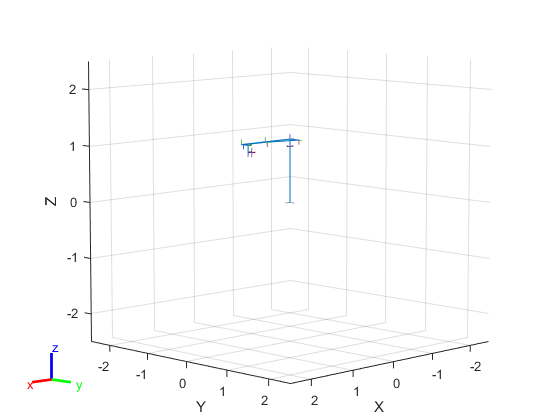

figure(1);
robot.show();
hold on
rosrobot.show();

#### 12. Compare the transforms in terms of end effector position and orientation

Compare the transforms between the robot bases and end effector frame *eelink* with `getTransform` for both models home configuration (*homeConfiguration*). Compare the transforms in terms of end effector position and orientation.

home=homeConfiguration(robot);
% Transform between world frame and end effector
thome=getTransform(robot,home,'eelink')

thome =    -1.0000   -0.0000    0.0000    1.1843
    0.0000   -0.0000    1.0000    0.2561
         0    1.0000    0.0000    1.0116
         0         0         0    1.0000



roshome = rosrobot.homeConfiguration();
% Transform between world frame and end effector
rosthome = rosrobot.getTransform(roshome,'ee_link')

rosthome =    -0.0000    1.0000    0.0000    1.1843
    1.0000    0.0000         0    0.2561
   -0.0000    0.0000   -1.0000    1.0116
         0         0         0    1.0000



% thome and rosthome are not equal, due to rotation

#### 13. Transfomation between the end effector frame in euler angles

You notice that there is a discrepancy between the orientation of the end effector frame of your model (*robot*) and the ROS URDF model (*rosrobot*). Determine the transform $$\mathbf{H}_{d}$$ between both end effector frames $$\mathbf{H}_{eerobot}$
$ and $$\mathbf{H}_{eerosrobot}$$ the robots respective world frames according to:


$$\mathbf{H}_d= \mathbf{H}_{eerobot}^{-1} \mathbf{H}_{eerosrobot}
$$
 

% determine transform between ros ee_link and eelink and add it to eelink
delta=  inv(thome)*rosthome

delta =     0.0000   -1.0000   -0.0000   -0.0000
   -0.0000    0.0000   -1.0000    0.0000
    1.0000    0.0000   -0.0000    0.0000
         0         0         0    1.0000


% Revert the eerobot transform first and then apply the eerosrobot
% transform to get rid of the discrepancy

What are the corresponding angles $$\phi, \theta, \psi$$ of the transform $$\mathbf{H}_d$
$?

% convert to Euler Angles, phi=0, theta=-pi, psi=pi
euldelta=tform2eul(delta);

#### 14. Compensate the orientation discrepancy

Compensate the the orientation discrepancy of the end effector frame by replacing the transform of the fixed end effector joint in the *robot* RigidBodyObject with $$\mathbf{H}_d$$ using `setFixedTransform`. You can access the transform from the struct array with `robot.Bodies{1,8}.Joint`.

% correct orientation of end effector frame
robot.Bodies{1,8}.Joint.setFixedTransform(delta);
% thome after orientation compensation
thome = robot.getTransform(home,'eelink')

thome =    -0.0000    1.0000    0.0000    1.1843
    1.0000    0.0000         0    0.2561
   -0.0000    0.0000   -1.0000    1.0116
         0         0         0    1.0000


#### 15. Compare both models

Plot both robots link frames with `show` and confirm that with the correction in orientation both end effector frames coincide. In the following assignments utilize the ROS URDF-robot model *rosrobot*.

figure(3);
show(robot);
hold on;
show(rosrobot);
hold off;
if (norm(thome-rosthome)< 1.0e-7)
    disp('end effector frame UR10 robot and UR10 ROS robot are equal');
else
    disp('end effector frame UR10 robot and UR10 ROS robot are not equal');
end

end effector frame UR10 robot and UR10 ROS robot are equal


#### 16. Create a random configuration

Create a random configuration *randq* of *rosrobot* with `randConfiguration`. Visualize the robot in that configuration with *show*.

% generate random arm configuration
randq=randomConfiguration(robot);
% copy joint configuration structure for rosrobot
rosrandq=JointVec2JointConf(rosrobot,[randq.JointPosition]);
% Transform between world frame and end effector
trandq=getTransform(robot,randq,'eelink')

trandq =     0.0802   -0.3864    0.9188   -0.1072
    0.4784    0.8236    0.3046    1.0652
   -0.8745    0.4152    0.2509    1.3859
         0         0         0    1.0000


rostrandq=getTransform(rosrobot,rosrandq,'ee_link')

rostrandq =     0.0802   -0.3864    0.9188   -0.1072
    0.4784    0.8236    0.3046    1.0652
   -0.8745    0.4152    0.2509    1.3859
         0         0         0    1.0000



if (norm(trandq-rostrandq)< 1.0e-7)
    disp('end effector frame UR10 robot and UR10 ROS robot are equal');
else
    disp('end effector frame UR10 robot and UR10 ROS robot are not equal');
end

end effector frame UR10 robot and UR10 ROS robot are equal



figure(4);
robot.show(randq);
hold on;
rosrobot.show(rosrandq);
hold off;

## Rviz Visualization Package for UR10 Robot

Follow the steps in the instruction files in the moodle course:

- [Instructions on VM and ROS](https://moodle.tu-dortmund.de/mod/resource/view.php?id=698961)

- [Instructions on UR ROS Package](https://moodle.tu-dortmund.de/mod/resource/view.php?id=698965)

- [Instructions on Matlab and ROS](https://moodle.tu-dortmund.de/mod/resource/view.php?id=698963)

#### 17. Install the UR10 RVIZ simulation in ROS from the command line

Install the UR10 package that contains the RVIZ simulation in ROS from the command line. Fetch the `universal_robot` package from *Assignment Forward Kinematics* in the moodle course. Follow the [instructions on UR ROS Package](https://moodle.tu-dortmund.de/mod/resource/view.php?id=698965).

#### 18. Launch the UR10 visualization package

If the build is successful, you launch the UR10 visualisation package with:

`        roslaunch ur_launch ur10_sim_visualization.launch use_joint_publisher:=true`

With the parameter *use_joint_publisher* set to *true,* ROS also starts a default *JointStatePublisher*. In case Matlab is supposed to publish joint states set the `parameter to ``false``.`

Move the robot arm visualization using the joint position sliders of the *JointStatePublisher* GUI.

## Connect to ROS Master and List Topics

#### 19. Launch the UR10 visualisation package with external publisher

Launch the UR10 visualisation package with external publisher:

        `roslaunch ur_launch ur10_sim_visualization.launch use_joint_publisher:=false`

#### 20. Connect to ROS master

Connect to the ROS master on the local host from Matlab with `rosinit`.

% rosinit
% rosinit('192.168.178.46')
% rosinit('192.168.2.113')

#### 21. Query the topics that are currently available on the network

Query the topics that are currently available on the network. Obtain information about the topic *'/ur10/joint_states'*  in particular the message type.

rostopic list
rostopic info /ur10/joint_states

## ROS Subscriber and Publisher

#### 22. Create a publisher

Create a publisher *jointstatepublisher* for the topic */ur10/joint_states* with the message *sensor_msgs/JointState*. 

jointstatepublisher = rospublisher('/ur10/joint_states','sensor_msgs/JointState');

/chatter                                                     
/clicked_point                                               
/initialpose                                                 
/move_base_simple/goal                                       
/robot_workspace_monitor/dynamic_obstacle_marker             
/robot_workspace_monitor/dynamic_obstacle_marker_array       
/robot_workspace_monitor/human_marker                        
/robot_workspace_monitor/human_marker_array                  
/robot_workspace_monitor/interactive_obstacle_marker/feedback
/robot_workspace_monitor/interactive_obstacle_marker/update  
/robot_workspace_monitor/obstacle_1_path                     
/robot_workspace_monitor/obstacle_2_path                     
/robot_workspace_monitor/obstacles                           
/robot_workspace_monitor/plane_marker                        
/robot_workspace_monitor/plane_marker_array                  
/robot_workspace_monitor/static_obstacle_marker              
/robot_w

#### 23. Create an empty message for a topic

Create an empty message *jointstatemsg* for that topic with `rosmessage`. Inspect the field structure of  *jointstatemsg.*

jointstatemsg = rosmessage('sensor_msgs/JointState');

Type: sensor_msgs/JointState
 
Publishers:
 
Subscribers:
* /robot_state_publisher (http://ubuntu:43097/)
* /ur_distance_publisher (http://ubuntu:42181/)
* /rostopic_4993_1606855912606 (http://ubuntu:35653/)


#### 24. Copy the corresponding fields to the fields of the message

Copy the corresponding fields *JointName* and *JointPosition* of the Matlab configuration object *randq* to the fields *Name* and *Position* of the empty *jointstatemsg*.

rosrandq=randomConfiguration(rosrobot);
for i=1:6
    jointstatemsg.Name(i)=cellstr(rosrandq(i).JointName);
    jointstatemsg.Position(i)=rosrandq(i).JointPosition;
end

#### 25. Assign the current ros time

Assign the current ros time `rostime('now')` to the field *Stamp* in the *Header* of  *jointstatemsg*.

jointstatemsg.Header.Stamp=rostime('now');

#### 26. Publish messages

Publish the message *jointstatemsg* on *jointstatepublisher*. The robot visualization in RVIZ should reflect the new joint configuration.

jointstatepublisher.send(jointstatemsg);

If the sent messages are not received and there is no roboter movement in RVIZ, check your firewall settings.

#### 27. Implement code that simulates a robot movement through a discrete sequence of intermediate states

Implement Matlab code that simulates a robot movement through a discrete sequence of intermediate states


$$\mathbf{q}_t = \mathbf{q}_i + (\mathbf{q}_f-\mathbf{q}_i) \frac{t}{t_f}$$


from the initial joint configuration $$\mathbf{q}_i=[0 \ 0 \ 0 \ 0 \ 0 \ 0]$$ to the target joint configuration $$\mathbf{q}_f=[\pi/2 \ -\pi/2 \ \pi/2 \ 0 \ \pi/3 \ -\pi/3)]$$ over a period of $$t \in [0 \ t_f]$$ with seconds. The helper function

	`function [ configuration ] = JointVec2JointConf( robot, q )`

provided in Moodle maps an ordinary joint vector into the Robotics System Toolbox joint configuration expected for messages of the type  *sensor_msgs/JointState.*

The template below provides a rated while loop that employs a rate object to iterate at a fixed rate independent of the actual computation time of a loop iteration.

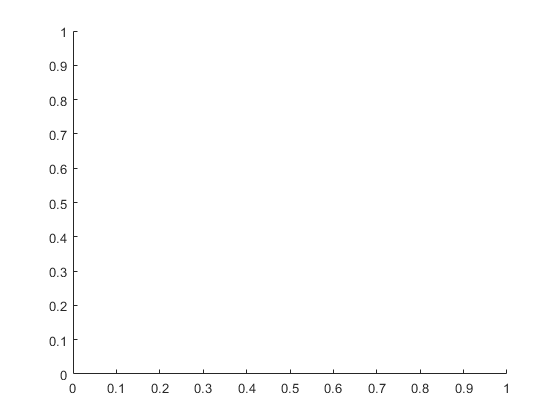

Loop ended


goIntoLoop = true;

displayMatlab = false;
displayRVIZ = true;

if goIntoLoop
    rate = 20; % Rate of 20 Hz
    rateObj=robotics.Rate(rate);
    maxTime = 4;
    
    % prepare loop
    qi=[0 0 0 0 0 0];
    qt=[pi/2 -pi/2 pi/2 0 pi/3 -pi/3];
    figure(6);
    hold off;
    rateObj.reset;  % reset time at the beginning of the loop
    while rateObj.TotalElapsedTime < maxTime
        
        qinterp=qi+(qt-qi)*min(1,rateObj.TotalElapsedTime/maxTime);
        rosqinterp=JointVec2JointConf(rosrobot,qinterp);
        if (displayMatlab)
            rosrobot.show(rosqinterp);
        end
        if (displayRVIZ)
            for i=1:6
                jointstatemsg.Name(i)=cellstr(rosqinterp(i).JointName);
                jointstatemsg.Position(i)=rosqinterp(i).JointPosition;
            end
            jointstatemsg.Header.Stamp=rostime('now');
            send(jointstatepublisher,jointstatemsg);
        end
        waitfor(rateObj);
    end
    
    disp('Loop ended');
end